# Introduction: State Space 

## Model

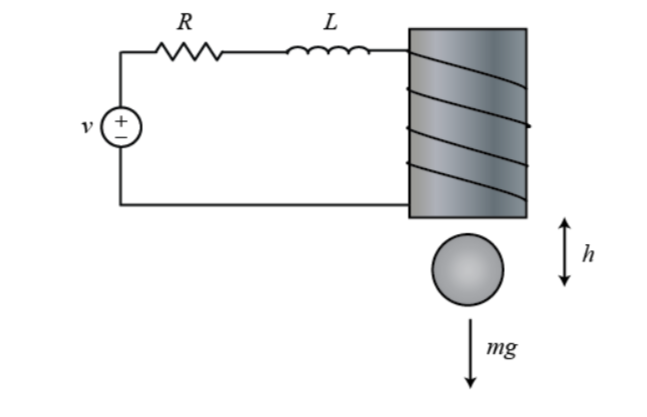


$$m\frac{d^2 h}{{\mathrm{dt}}^2 }\;=\mathrm{mg}-\frac{{\mathrm{Ki}}^2 }{h}$$



$$V=L\frac{\mathrm{di}}{\mathrm{dt}}\;+\;i$$


Linearize the equation at h = 0.1 where is the equilibrium point, and state variable $x={\left\lbrack \Delta h,\Delta \overset{\ldotp }{h} ,i\right\rbrack }^T$, the corresponding state-space equation is as follows

A = [ 0   1   0
     980  0  -2.8
      0   0  -100 ];

B = [ 0
      0
      100 ];

C = [ 1 0 0 ];

## Stability

The system is not stable.

roots = eig(A)

roots =    31.3050
  -31.3050
 -100.0000


## Open-loop response

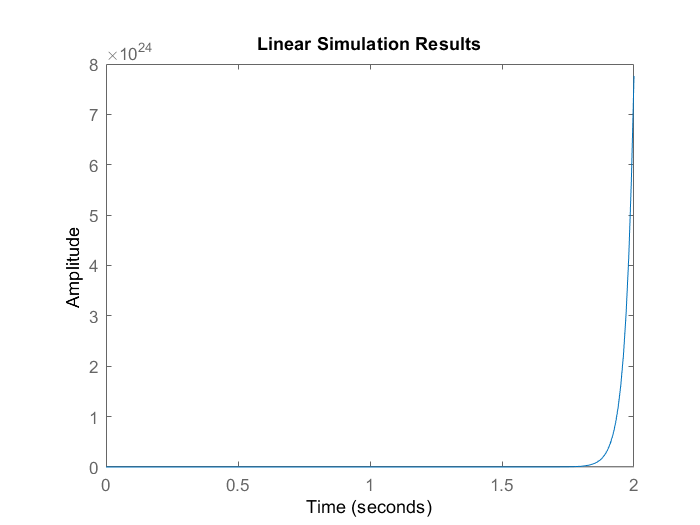

sys_ol = ss(A, B, C, 0);
t = 0:0.01:2;
u = zeros(size(t)); % zero input
x0 = [0.01; 0; 0];
% non-zero initial condition output
% show when the ball is off its equilibrium point
lsim(sys_ol, u, t, x0); 

## Control Design Using Pole Placement (full state feedback)

Requirments

- 5% overshoot

- Settling time less than 0.5 sec

It means that zeta > 0.7, and roots with real part is smaller than -10.

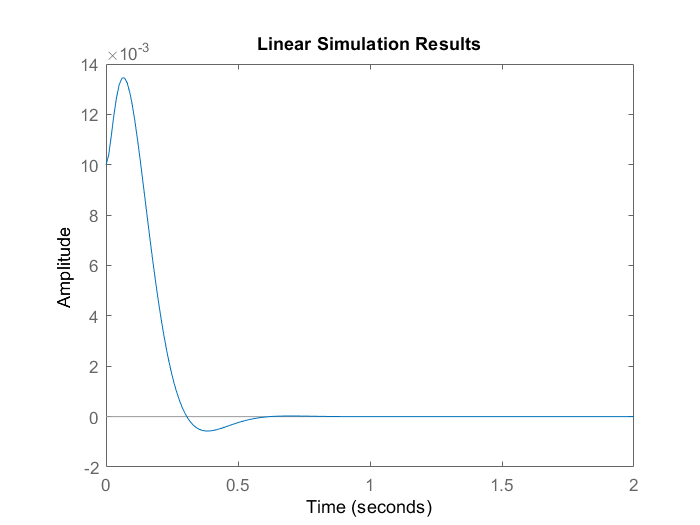

p1 = -10 + 10i;
p2 = -10 - 10i;
p3 = -50; % bring minimum effect to the second order system approximation

% find the gain for the full state feedback u = -Kx
K = place(A, B, [p1 p2 p3]);

% simulate close-loop response
sys_cl = ss(A - B*K, B, C, 0);
% for close system 
% x_dot = (A-BK)x + B*0
% y = cx 
% thus the closed loop response is as above
lsim(sys_cl, u, t, x0);

From inspection, we can see the overshoot is too large (there are also zeros in the transfer function which can increase the overshoot; you do not explicitly see the zeros in the state-space formulation). Try placing the poles further to the left to see if the transient response improves (this should also make the response faster).

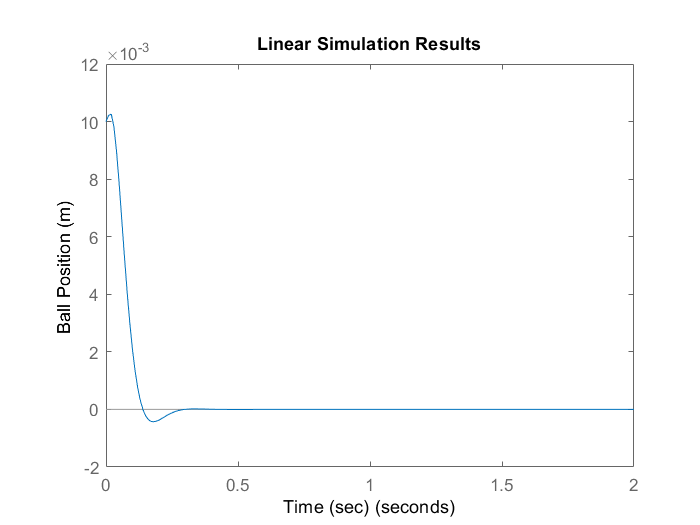

p1 = -20 + 20i;
p2 = -20 - 20i;
p3 = -100;

K = place(A,B,[p1 p2 p3]);
sys_cl = ss(A-B*K,B,C,0);
% or use sys_cl = feedback(sys_ol, K)
lsim(sys_cl,u,t,x0);
xlabel('Time (sec)')
ylabel('Ball Position (m)')

**Note:** If you want to place two or more poles at the same position, `place` will not work. You can use a function called `acker` which achieves the same goal (but can be less numerically well-conditioned):

`K = acker(A,B,[p1 p2 p3])`

## `Introducing Reference Input`

Now, we will take the control system as defined above and apply a step input (we choose a small value for the step, so we remain in the region where our linearization is valid). Replace `t`, `u` , and `lsim` in your `m-file` with the following:

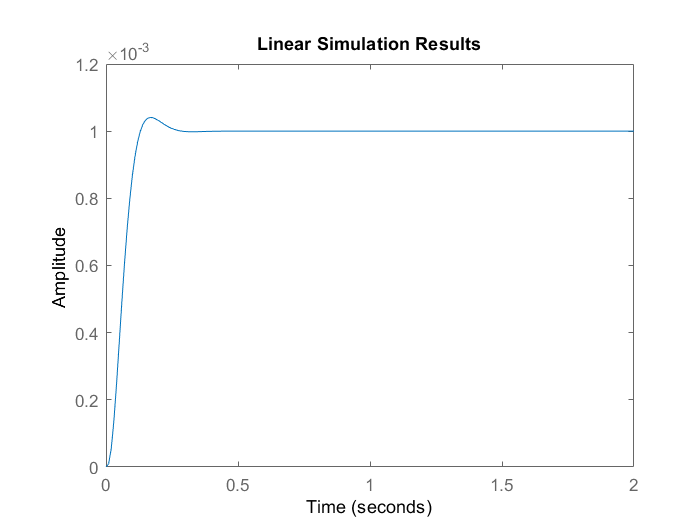

N = dcgain(sys_cl); % dc gain of the closed system
u_step = 0.001*ones(size(t));
lsim(sys_cl, u_step/N, t);axis([0 2 0 1.2*10^-3]); % scale factor is 1/dc gain of the close system

## Observer Design (for system can not be full-state feedback)

op1 = -100;
op2 = -101;
op3 = -102;
L = place(A',C',[op1 op2 op3])';

Because of the duality between controllability and observability, we can use the same technique used to find the control matrix by replacing the matrix  by the matrix  and taking the transposes of each matrix:

At = [ A-B*K             B*K
       zeros(size(A))    A-L*C ];

Bt = [    B/N
       zeros(size(B)) ];

Ct = [ C    zeros(size(C)) ];
sys = ss(At,Bt,Ct,0);

lsim(sys,zeros(size(t)),t,[x0 x0]);

Error using DynamicSystem/lsim (line 97)
The initial condition X0 must be a numeric vector without any NaN or Inf.


title('Linear Simulation Results (with observer)')
xlabel('Time (sec)')
ylabel('Ball Position (m)')